load('proj7wordsData.mat');

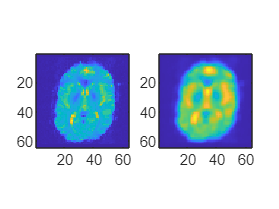

[nRows, nCols, nTimes] = size(image_3d);
for time = 1:nTimes
    image_m = squeeze(image_3d(:, :, time));
    smoothImage_m = conv2(image_m, ones(4), 'same');
    imageWord_3d(:, :, time) = smoothImage_m;
    
    % Insert code here to display both the original and smoothed 
    % images (in one figure):
    if time == 1 
        figure
        subplot(1,2,1)
        imagesc(image_m)
        axis image
        subplot(1,2,2)
        imagesc(smoothImage_m)
        axis image
    end 
end

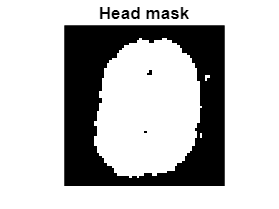

% Create head mask
% Use the magnitude of the first image to form a binary mask  
image_m = squeeze(image_3d(:, :, 1));
mask_m = (image_m > 0.1*max(image_m(:))); % set mask at higher threshold 
figure
imagesc(mask_m)
colormap(gray)
axis image
axis off
title('Head mask')

% normalize by L2 norm
meanWordNormalized = (sound_v - mean(sound_v));
normWordSound_v = meanWordNormalized./norm(meanWordNormalized,2);

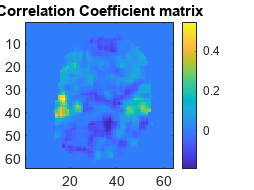

rWord_m = zeros(nRows, nCols);

for row = 1:nRows
    for col = 1: nCols
        if (mask_m(row, col) == 1)
            data_v = squeeze(imageWord_3d(row, col, :));
            % Insert code here to transform the data_v to have zero mean 
            % and unit norm.  Call this vector 
            meanNormalized = (data_v - mean(data_v));
            normData_v = meanNormalized./norm(meanNormalized,2);

            % Calculate the correlation coefficient of normData_v and 
            % normSound_v:
            rWord_m(row, col) = sum(normData_v.* normWordSound_v);
        end
    end
end 
figure
imagesc(rWord_m)
colorbar
title('Correlation Coefficient matrix')

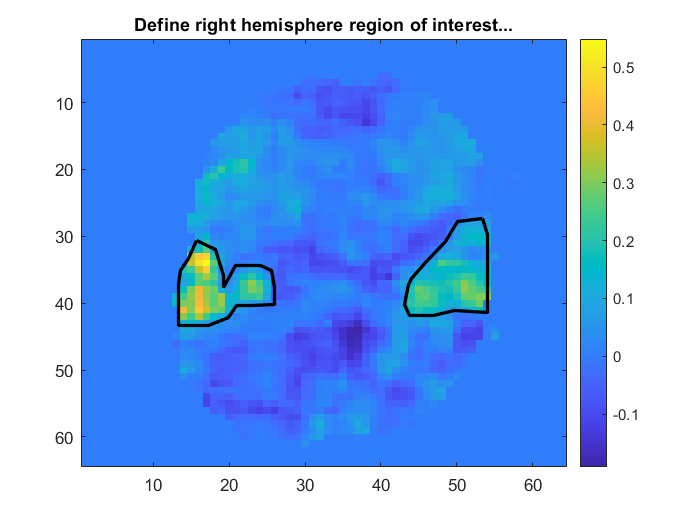

title('Define left hemisphere region of interest...')
[leftRoiMask_m, xLeft_v, yLeft_v] = roipoly;
line(xLeft_v, yLeft_v, 'LineWidth', 2, 'Color', 'k')

title('Define right hemisphere region of interest...')
[rightRoiMask_m, xRight_v, yRight_v] = roipoly;
line(xRight_v, yRight_v, 'LineWidth', 2, 'Color', 'k')

roiMask_m = rightRoiMask_m + leftRoiMask_m;

save('roiMasks.mat', ...
    "leftRoiMask_m","xLeft_v","yLeft_v", ...
    'rightRoiMask_m','xRight_v','yRight_v');

load('roiMasks.mat')
roiMask_m = rightRoiMask_m + leftRoiMask_m;

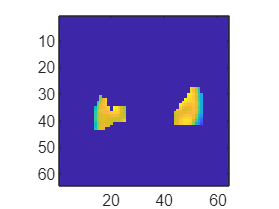

roiWordSignal_v = zeros(nTimes, 1);
for time = 1:nTimes
    roiWordSignal_v(time) = sum(sum(roiMask_m.*imageWord_3d(:, :, time)));    
    imageSignal_3d(:, :, time) = roiMask_m.*imageWord_3d(:, :, time);
    if time == 1 
        figure
        imagesc(imageSignal_3d(:, :, time))
        axis image
    end
end

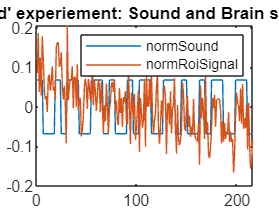

time_v = 1:1:nTimes;
% normalize by L2 norm
roiWordSignalNormalized = (roiWordSignal_v - mean(roiWordSignal_v));
normWordRoiSignal_v = roiWordSignalNormalized./norm(roiWordSignalNormalized,2);
plot(time_v, normWordSound_v, time_v, normWordRoiSignal_v)
legend('normSound', 'normRoiSignal')
title("'Word' experiement: Sound and Brain signals")

uniqueWordSounds = unique(normWordSound_v)

uniqueWordSounds =    -0.0680
    0.0680


stim_v = 0;
rest_v = 0;
restTime_v = [];
for time = 1:nTimes 
    if normWordSound_v(time) == uniqueWordSounds(2)
        if stim_v==0
            stim_v = roiWordSignal_v(time);
        else
            stim_v = [stim_v roiWordSignal_v(time)];
        end
    else 
        if rest_v==0 
            rest_v = roiWordSignal_v(time);
        else
            rest_v = [rest_v roiWordSignal_v(time)];
        end
        restTime_v(end+1) = time;
    end
end

meanWordStim = mean(stim_v)

meanWordStim = 1.9855e+07

meanWordRest = mean(rest_v)

meanWordRest = 1.9766e+07

stdWordStim = std(stim_v)

stdWordStim = 1.3927e+05

stdWordRest = std(rest_v)

stdWordRest = 1.3731e+05

stdWordNoise = sqrt(0.5* (stdWordStim^2 + stdWordRest^2))

stdWordNoise = 1.3829e+05

cnrWord = (meanWordStim - meanWordRest)/stdWordNoise

cnrWord = 0.6411

## Word experiment

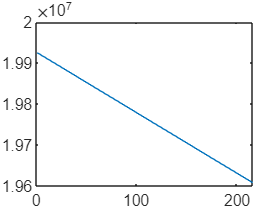

coeff_v = polyfit(restTime_v, rest_v, 1); % 1 since linear
wordSlope = coeff_v(1); % slope
wordBias = coeff_v(2);

wordDrift = (wordSlope.*(1:nTimes) + wordBias)';
plot(time_v, wordSlope.*(1:nTimes) + wordBias)

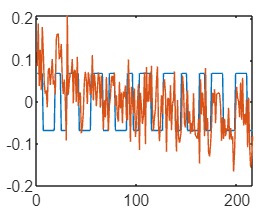

correctedWord_v = roiWordSignal_v - wordDrift;

time_v = 1:1:nTimes;
% normalize by L2 norm
correctedWordNormalized = (correctedWord_v - mean(correctedWord_v));
normCorrectedWord_v = correctedWordNormalized./norm(correctedWordNormalized,2);

plot(time_v, normWordSound_v, time_v, normWordRoiSignal_v)

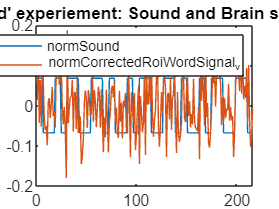


plot(time_v, normWordSound_v, time_v, normCorrectedWord_v)
legend('normSound', 'normCorrectedRoiWordSignal_v')
title("'Word' experiement: Sound and Brain signals")


wordCorrectedStim_v = 0;
wordCorrectedRest_v = 0;
for time = 1:nTimes 
    if normWordSound_v(time) == uniqueWordSounds(2)
        if wordCorrectedStim_v==0
            wordCorrectedStim_v = correctedWord_v(time);
        else
            wordCorrectedStim_v = [wordCorrectedStim_v correctedWord_v(time)];
        end
    else 
        if wordCorrectedRest_v==0 
            wordCorrectedRest_v = correctedWord_v(time);
        else
            wordCorrectedRest_v = [wordCorrectedRest_v correctedWord_v(time)];
        end
    end
end

meanCorrectedWordStim = mean(wordCorrectedStim_v)

meanCorrectedWordStim = 8.8663e+04

meanCorrectedWordRest = mean(wordCorrectedRest_v)

meanCorrectedWordRest = -1.1728e-09

stdCorrectedWordStim = std(wordCorrectedStim_v)

stdCorrectedWordStim = 1.1677e+05

stdCorrectedWordRest = std(wordCorrectedRest_v)

stdCorrectedWordRest = 1.0142e+05

stdCorrectedWordNoise = sqrt(0.5* (stdCorrectedWordStim^2 + stdCorrectedWordRest^2))

stdCorrectedWordNoise = 1.0937e+05

cnrCorrectedWord = (meanCorrectedWordStim - meanCorrectedWordRest)/stdCorrectedWordNoise

cnrCorrectedWord = 0.8107

## Center of activation

[cols_m, rows_m] = meshgrid(1:nCols, transpose(1:nRows));
wordLeftCenterRow = sum(sum(leftRoiMask_m.*rows_m.*rWord_m)) / ...
    sum(sum(leftRoiMask_m .* rWord_m));
wordLeftCenterCol = sum(sum(leftRoiMask_m.*cols_m.*rWord_m)) / ...
    sum(sum(leftRoiMask_m .* rWord_m));

wordRightCenterRow = sum(sum(rightRoiMask_m.*rows_m.*rWord_m)) / ...
    sum(sum(rightRoiMask_m .* rWord_m));
wordRightCenterCol = sum(sum(rightRoiMask_m.*cols_m.*rWord_m)) / ...
    sum(sum(rightRoiMask_m .* rWord_m));

save('wordCoordinates.mat' ...
    ,'wordLeftCenterCol','wordRightCenterCol' ...
    ,'wordLeftCenterRow','wordRightCenterRow')

## Chords

load('proj7chordsData.mat');

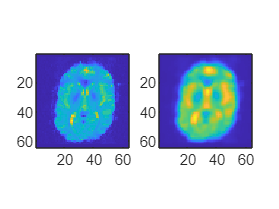

[nRows, nCols, nTimes] = size(image_3d);
for time = 1:nTimes
    image_m = squeeze(image_3d(:, :, time));
    smoothImage_m = conv2(image_m, ones(4), 'same');
    imageChord_3d(:, :, time) = smoothImage_m;
    
    % Insert code here to display both the original and smoothed 
    % images (in one figure):
    if time == 1 
        figure
        subplot(1,2,1)
        imagesc(image_m)
        axis image
        subplot(1,2,2)
        imagesc(smoothImage_m)
        axis image
    end 
end

% normalize by L2 norm
meanChordSoundNormalized = (sound_v - mean(sound_v));
normChordSound_v = meanChordSoundNormalized./norm(meanChordSoundNormalized,2);

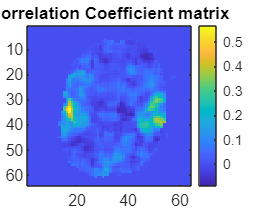

rChord_m = zeros(nRows, nCols);

for row = 1:nRows
    for col = 1: nCols
        if (mask_m(row, col) == 1)
            chordData_v = squeeze(imageChord_3d(row, col, :));
            % Insert code here to transform the data_v to have zero mean 
            % and unit norm.  Call this vector 
            meanChordNormalized = (chordData_v - mean(chordData_v));
            normChordData_v = meanChordNormalized./norm(meanChordNormalized,2);

            % Calculate the correlation coefficient of normData_v and 
            % normSound_v:
            rChord_m(row, col) = sum(normChordData_v.* normChordSound_v);
        end
    end
end 
figure
imagesc(rChord_m)
colorbar
title('Correlation Coefficient matrix')

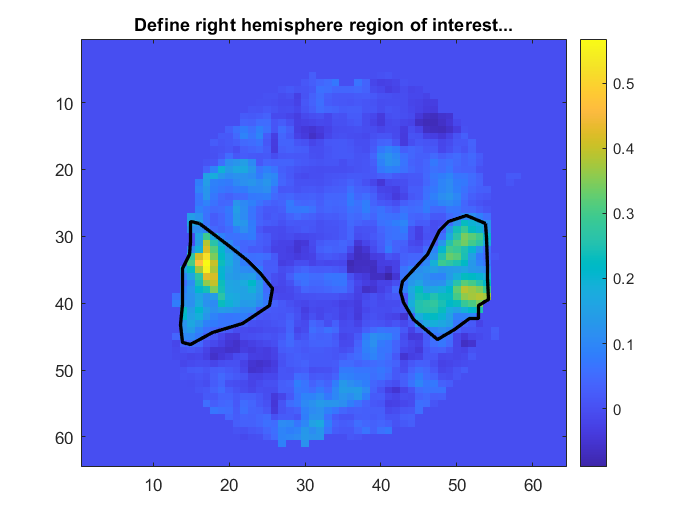

title('Define left hemisphere region of interest...')
[leftChordRoiMask_m, xLeft_v, yLeft_v] = roipoly;
line(xLeft_v, yLeft_v, 'LineWidth', 2, 'Color', 'k')

title('Define right hemisphere region of interest...')
[rightChordRoiMask_m, xRight_v, yRight_v] = roipoly;
line(xRight_v, yRight_v, 'LineWidth', 2, 'Color', 'k')

roiChordMask_m = rightChordRoiMask_m + leftChordRoiMask_m;

save('roiChordMasks.mat', ...
    "leftChordRoiMask_m","xLeft_v","yLeft_v", ...
    'rightChordRoiMask_m','xRight_v','yRight_v');

load('roiChordMasks.mat')
roiChordMask_m = rightChordRoiMask_m + leftChordRoiMask_m;

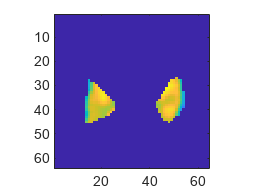

roiChordSignal_v = zeros(nTimes, 1);
for time = 1:nTimes
    roiChordSignal_v(time) = sum(sum(roiChordMask_m.*imageChord_3d(:, :, time)));    
    imageChordSignal_3d(:, :, time) = roiChordMask_m.*imageChord_3d(:, :, time);
    if time == 1 
        figure
        imagesc(imageChordSignal_3d(:, :, time))
        axis image
    end
end

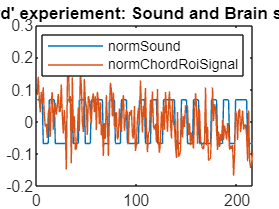

time_v = 1:1:nTimes;
% normalize by L2 norm
roiChordSignalNormalized = (roiChordSignal_v - mean(roiChordSignal_v));
normChordRoiSignal_v = roiChordSignalNormalized./norm(roiChordSignalNormalized,2);
plot(time_v, normChordSound_v, time_v, normChordRoiSignal_v)
legend('normSound', 'normChordRoiSignal')
title("'Chord' experiement: Sound and Brain signals")

mean(roiChordSignalNormalized)

ans = 1.7937e-09

norm(normChordRoiSignal_v)

ans = 1

uniqueChordSounds = unique(normChordSound_v)

uniqueChordSounds =    -0.0680
    0.0680


chordStim_v = 0;
chordRest_v = 0;
chordRestTime_v = [];
for time = 1:nTimes 
    if normChordSound_v(time) == uniqueChordSounds(2)
        if chordStim_v==0
            chordStim_v = roiChordSignal_v(time);
        else
            chordStim_v = [chordStim_v roiChordSignal_v(time)];
        end
    else 
        if chordRest_v==0 
            chordRest_v = roiChordSignal_v(time);
        else
            chordRest_v = [chordRest_v roiChordSignal_v(time)];
        end
        chordRestTime_v(end+1) = time;
    end
end

meanChordStim = mean(chordStim_v)

meanChordStim = 2.7085e+07

meanChordRest = mean(chordRest_v)

meanChordRest = 2.6960e+07

stdChordStim = std(chordStim_v)

stdChordStim = 1.4243e+05

stdChordRest = std(chordRest_v)

stdChordRest = 1.5979e+05

stdChordNoise = sqrt(0.5* (stdChordStim^2 + stdChordRest^2))

stdChordNoise = 1.5136e+05

cnrChord = (meanChordStim - meanChordRest)/stdChordNoise

cnrChord = 0.8274

## Subtract drift

%Estimate the signal drift in your ROI 
% by fitting the signal during the %stimulus off’ 
% with a straight line (using polyfit

## Chord experiment

coeff_v = polyfit(chordRestTime_v, chordRest_v, 1); % 1 since linear
chordSlope = coeff_v(1) % slope

chordSlope = -1.2773e+03

chordBias = coeff_v(2)

chordBias = 2.7099e+07

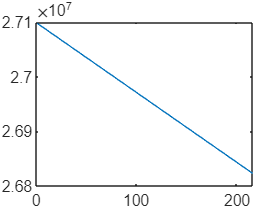


chordDrift = (chordSlope.*(1:nTimes) + chordBias)';
plot(time_v, chordSlope.*(1:nTimes) + chordBias)

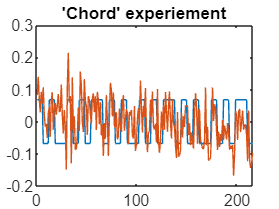

correctedChord_v = roiChordSignal_v - chordDrift;

time_v = 1:1:nTimes;
% normalize by L2 norm
correctedChordNormalized = (correctedChord_v - mean(correctedChord_v));
normCorrectedChord_v = correctedChordNormalized./norm(correctedChordNormalized,2);

plot(time_v, normChordSound_v, time_v, normChordRoiSignal_v)
title("'Chord' experiement")

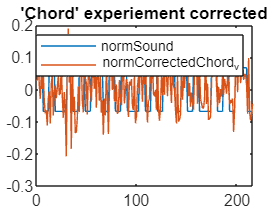

plot(time_v, normChordSound_v, time_v, normCorrectedChord_v)
legend('normSound', 'normCorrectedChord_v')
title("'Chord' experiement corrected")



chordCorrectedStim_v = 0;
chordCorrectedRest_v = 0;
for time = 1:nTimes 
    if normChordSound_v(time) == uniqueChordSounds(2)
        if chordCorrectedStim_v==0
            chordCorrectedStim_v = correctedChord_v(time);
        else
            chordCorrectedStim_v = [chordCorrectedStim_v correctedChord_v(time)];
        end
    else 
        if chordCorrectedRest_v==0 
            chordCorrectedRest_v = correctedChord_v(time);
        else
            chordCorrectedRest_v = [chordCorrectedRest_v correctedChord_v(time)];
        end
    end
end

meanCorrectedChordStim = mean(chordCorrectedStim_v)

meanCorrectedChordStim = 1.2523e+05

meanCorrectedChordRest = mean(chordCorrectedRest_v)

meanCorrectedChordRest = -1.5177e-09

stdCorrectedChordStim = std(chordCorrectedStim_v)

stdCorrectedChordStim = 1.3408e+05

stdCorrectedChordRest = std(chordCorrectedRest_v)

stdCorrectedChordRest = 1.3853e+05

stdCorrectedChordNoise = sqrt(0.5* (stdCorrectedChordStim^2 + stdCorrectedChordRest^2))

stdCorrectedChordNoise = 1.3632e+05

cnrCorrectedChord = (meanCorrectedChordStim - meanCorrectedChordRest)/stdCorrectedChordNoise

cnrCorrectedChord = 0.9186

##  ------- Center of activation ------

[cols_m, rows_m] = meshgrid(1:nCols, transpose(1:nRows));
chordLeftCenterRow = sum(sum(leftChordRoiMask_m.*rows_m.*rChord_m)) / ...
    sum(sum(leftChordRoiMask_m .* rChord_m));
chordLeftCenterCol = sum(sum(leftChordRoiMask_m.*cols_m.*rChord_m)) / ...
    sum(sum(leftChordRoiMask_m .* rChord_m));

chordRightCenterRow = sum(sum(rightChordRoiMask_m.*rows_m.*rChord_m)) / ...
    sum(sum(rightChordRoiMask_m .* rChord_m));
chordRightCenterCol = sum(sum(rightChordRoiMask_m.*cols_m.*rChord_m)) / ...
    sum(sum(rightChordRoiMask_m .* rChord_m));

centroidsImage_m = squeeze(image_3d(:, :, 1));
centroidsImage_m = centroidsImage_m/max(centroidsImage_m(:));
imagesc(centroidsImage_m), axis image, axis off
title('Center of activations - Red/Word, White/Chord')
hold on;
plot(wordLeftCenterCol,wordLeftCenterRow,'rx', 'MarkerSize', 5);
plot(wordRightCenterCol,wordRightCenterRow,'rx', 'MarkerSize', 5);
plot(chordLeftCenterCol,chordLeftCenterRow,'wx', 'MarkerSize', 5);
plot(chordRightCenterCol,chordRightCenterRow,'wx', 'MarkerSize', 5);
colorbar